## Rot_Wing control Moment definition

In this file we will define the mathematical model of the control moment for the rotating wing drone. 

### Motors modelling

The first step is to model the output thrust as a function of rpm. This is performed on a motor test benchmark at different airspeeds. For more details on the curves check file *"wind_tunnel_prop_plots"*.

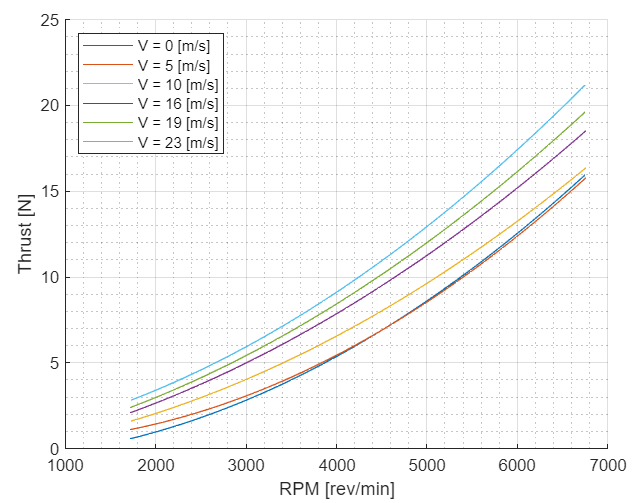

**TO DO model with changing airspeed**

Assume quadratic relationship between thrust and rpm:


$$T\left(\textrm{rpm}\right)=a*{\textrm{rpm}}^2 +b*\textrm{rpm}+c=3\ldotp 48e-7*{\textrm{rpm}}^2 +1\ldotp 11\;e-4*\textrm{rpm}-0\ldotp 651$$


Assuming a linear relationship between commanded thrust signal and achived rpm, it is possible to scale the thrust curve with respect to the paparazzi command scaling. 


$$\textrm{pprz}\left(\textrm{rpm}\right)=\frac{9600-0}{6800-1800}*\left(\textrm{rpm}-1800\right)+0=$$

$$1\ldotp 92\;\textrm{rpm}-3456\Longrightarrow \textrm{rpm}=\frac{\textrm{pprz}+3456}{1\ldotp 92}=0\ldotp 521\;\textrm{pprz}+1800$$
 


$$T\left(\textrm{pprz}\right)=a*\left(0\ldotp 521\;\textrm{pprz}+1800\right){\;}^2 +b*\left(0\ldotp 521\;\textrm{pprz}+1800\right)+c=9\ldotp 446e-8\;{\textrm{pprz}}^2 +7\ldotp 11e-4\;\textrm{pprz}+0\ldotp 67632$$


Using a quadratic approximation can complicate the definition of the control moment matrix. The use of a linear approximation might be more straightforward. How wrong would a linear approximation be?


$$T_{\textrm{linear}} \left(\textrm{pprz}\right)=a*\textrm{pprz}+b=\frac{16-0}{9600-0}*\textrm{pprz}+0=1\ldotp 667\;e-3\;\textrm{pprz}$$


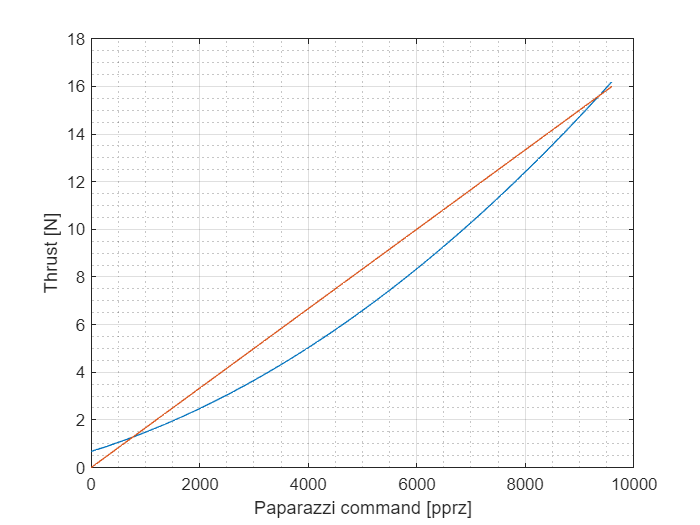

pprz = linspace(0,9600);
T_f = 9.446e-8 *pprz.^2+7.11e-4*pprz+0.67632;
T_lin = 1.667e-3*pprz;
figure(1)
clf
plot(pprz,T_f)
hold on
plot(pprz,T_lin)
grid on 
grid minor
xlabel("Paparazzi command [pprz]")
ylabel("Thrust [N]")

RMSE = rms((T_f-T_lin)/T_f)

RMSE = 0.1023

The RMSE indicates an average deviation of 10%. 

Similarly, also the exerted torque can be modelled

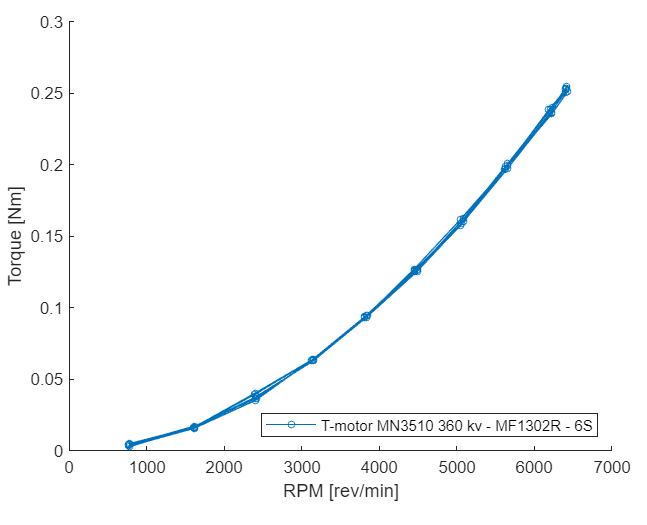


$$\begin{array}{l}
Q\left(\textrm{rpm}\right)=a\;{\textrm{rpm}}^2 +b\;\textrm{rpm}+c=5\ldotp 730\;e-9\;{\textrm{rpm}}^2 +3\ldotp 124e-6\;\textrm{rpm}-2\ldotp 80e-3\\
Q\left(\textrm{pprz}\right)=1\ldotp 555e-9\;{\textrm{pprz}}^2 +1\ldotp 20\;e-5\;\textrm{pprz}+2\ldotp 139\;e-2
\end{array}$$


for linear approximation the slopw is 2.604 e -5

Now the moment around the CG generated by a motor can be modelled as the cross product of the moment arm (b) in direction (j) and the force vector in direction (i) .:


$$M_{\textrm{mot}} \left(\textrm{pprz},\Lambda \right)=b\left(\Lambda \right)\times T\;\left(\textrm{pprz},\delta_{\textrm{mot}} \right)$$


$j_0 =\left\lbrack \begin{array}{c}
x_{\textrm{mot}} -x_{\textrm{rp}} \\
y_{\textrm{mot}} -y_{\textrm{rp}} \\
z_{\textrm{mot}} -z_{\textrm{rp}} 
\end{array}\right\rbrack$ and $s_{\textrm{cg}} =$$\left\lbrack \begin{array}{c}
{x_{\textrm{rp}} -x}_{\textrm{cg}} \\
y_{\textrm{rp}} -y_{\textrm{cg}} \\
z_{\textrm{rp}} -z_{\textrm{cg}} 
\end{array}\right\rbrack$

The arm is defined as :


$$b\left(\Lambda \right)=\left\lbrack \begin{array}{c}
b_x \\
b_y \\
b_z 
\end{array}\right\rbrack =R_z \left(-\Lambda \right){\;j}_0 \;b\;+s_{\textrm{cg}} =\left\lbrack \begin{array}{ccc}
\cos \left(\Lambda \right) & -\sin \left(\Lambda \right) & 0\\
\sin \left(\Lambda \right) & \cos \left(\Lambda \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
j_{0_x } \\
j_{0_y } \\
j_{0_z } 
\end{array}\right\rbrack b+\left\lbrack \begin{array}{c}
s_{{\textrm{cg}}_x } \\
s_{{\textrm{cg}}_y } \\
s_{{\textrm{cg}}_z } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\cos \left(\Lambda \right)\;j_{0_x } -\sin \left(\Lambda \right)j_{0_y } \\
\sin \left(\Lambda \right)j_{0_x } +\cos \left(\Lambda \right)j_{0_y } \\
j_{0_z } 
\end{array}\right\rbrack b+\left\lbrack \begin{array}{c}
s_{{\textrm{cg}}_x } \\
s_{{\textrm{cg}}_y } \\
s_{{\textrm{cg}}_z } 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{c}
j_x \\
j_y \\
j_z 
\end{array}\right\rbrack b+\left\lbrack \begin{array}{c}
s_{{\textrm{cg}}_x } \\
s_{{\textrm{cg}}_y } \\
s_{{\textrm{cg}}_z } 
\end{array}\right\rbrack$$


The thrust vector accounting for a possible $\delta_{mot}$ around the arm of the motor is:


$$\begin{array}{l}
T\left(\textrm{pprz},\delta_{\textrm{mot}} \right)=\left\lbrack \begin{array}{c}
i_x \\
i_y \\
i_z 
\end{array}\right\rbrack T\left(\textrm{pprz}\right)\\
\textrm{According}\;\textrm{to}\;\textrm{the}\;\textrm{Rodriguez}\;\textrm{rotation}\;\textrm{formula}:\\
\left\lbrack \begin{array}{c}
i_x \\
i_y \\
i_z 
\end{array}\right\rbrack =\cos \left(\delta_{\textrm{mot}} \right)\left\lbrack \begin{array}{c}
{i_0 }_x \\
{i_0 }_y \\
{i_0 }_z 
\end{array}\right\rbrack +\sin \left(\delta_{\textrm{mot}} \right)\left(\left\lbrack \begin{array}{c}
j_x \\
j_y \\
j_z 
\end{array}\right\rbrack \times \left\lbrack \begin{array}{c}
{i_0 }_x \\
{i_0 }_y \\
{i_0 }_z 
\end{array}\right\rbrack \right)+\left(1-\cos \left(\delta_{\textrm{mot}} \right)\right)\left\lbrack \begin{array}{c}
j_x \\
j_y \\
j_z 
\end{array}\right\rbrack \left(\left\lbrack \begin{array}{c}
j_x \\
j_y \\
j_z 
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{c}
{i_0 }_x \\
{i_0 }_y \\
{i_0 }_z 
\end{array}\right\rbrack \right)
\end{array}$$


To this calculated moment we then need to add the estimated torque exerted. For this assume that the exerted torque is not affected by  $\delta_{mot}$.


$$M_{\textrm{tot}} \left(\textrm{pprz}\right)=b\times T\;\left(\textrm{pprz},\delta_{\textrm{mot}} \right)+\;Q\left(\textrm{pprz}\right)$$


clear all
syms  b_abs T_pprz Q_pprz omega_k k_t_k k_q_k delta_mot_k
syms Lambda 'real'
syms j0 [3,1] 'real'
syms i0 [3,1] 'real'
syms omega [4,1] 'real'
syms k_t [4,1] 'real'
syms k_q [4,1] 'real'
syms b [4,1] 'real'
syms delta_mot [4,1] 'real'
syms scg [3,1] 'real'
T(k_t_k,omega_k)= k_t_k*omega_k;
Q(k_q_k,omega_k)= k_q_k*omega_k;
j(j0.',Lambda) = [cos(Lambda)*j01-sin(Lambda)*j02;sin(Lambda)*j01+cos(Lambda)*j02;j03];
b_fun(Lambda,j0.', scg.', b_abs) = j(j01, j02, j03,Lambda).*b_abs+scg;
i(i0.',j0.', delta_mot_k) = cos(delta_mot_k).*i0+sin(delta_mot_k).*cross(j(j01, j02, j03,Lambda),i0)+(1-cos(delta_mot_k)).*j(j01, j02, j03,Lambda)*(dot(j(j01, j02, j03,Lambda),i0));
M(Lambda,i0.',j0.', scg.', b_abs,delta_mot_k,T_pprz,Q_pprz)=cross(b_fun(Lambda,j01, j02, j03, scg1, scg2, scg3, b_abs),i(i01,i02,i03,j01, j02, j03, delta_mot_k).*T_pprz)+ Q_pprz * abs(i0);


The full control moment definition for the four quadrotors is then defined as :

M_mot_full(Lambda,b.',k_t.',k_q.',omega.') = simplify( ...
  [ M(0,0,0,-1,1, 0, 0, scg1, scg2, scg3, b1,delta_mot1,T(k_t1,omega1),Q(k_q1,omega1)), ...
    M(Lambda,0,0,-1,0, 1, 0, scg1, scg2, scg3, b2,delta_mot2,T(k_t2,omega2),Q(k_q2,-omega2)), ...
    M(0,0,0,-1,-1, 0, 0, scg1, scg2, scg3, b3,delta_mot3,T(k_t3,omega3),Q(k_q3,omega3)), ...
    M(Lambda,0,0,-1,0, -1, 0, scg1, scg2, scg3, b4,delta_mot4,T(k_t4,omega4),Q(k_q4,-omega4))]);
disp(simplifyFraction(M_mot_full./(ones(3,4).*[omega1,omega2,omega3,omega4])))

The reduced form for cg=rp and no motor twist is:

M_mot(Lambda,b.',k_t.',k_q.',omega.')  = simplify( ...
  [ M(0,0,0,-1,1, 0, 0, 0, 0, 0, b1,0,T(k_t1,omega1),Q(k_q1,omega1)), ...
    M(Lambda,0,0,-1,0, 1, 0, 0, 0, 0, b2,0,T(k_t2,omega2),Q(k_q2,-omega2)), ...
    M(0,0,0,-1,-1, 0, 0, 0, 0, 0, b3,0,T(k_t3,omega3),Q(k_q3,omega3)), ...
    M(Lambda,0,0,-1,0, -1, 0, 0, 0, 0, b4,0,T(k_t4,omega4),Q(k_q4,-omega4))]);
G_mot(Lambda,b.',k_t.',k_q.') = simplifyFraction(M_mot./(ones(3,4).*[omega1,omega2,omega3,omega4]))

$$G\_mot(Lambda, b1, b2, b3, b4, k\_t1, k\_t2, k\_t3, k\_t4, k\_q1, k\_q2, k\_q3, k\_q4) = \left(\begin{array}{cccc} 0 & -b_{2}\,k_{\mathrm{t2}}\,\cos\left(\Lambda \right) & 0 & b_{4}\,k_{\mathrm{t4}}\,\cos\left(\Lambda \right)\\ b_{1}\,k_{\mathrm{t1}} & -b_{2}\,k_{\mathrm{t2}}\,\sin\left(\Lambda \right) & -b_{3}\,k_{\mathrm{t3}} & b_{4}\,k_{\mathrm{t4}}\,\sin\left(\Lambda \right)\\ k_{\mathrm{q1}} & -k_{\mathrm{q2}} & k_{\mathrm{q3}} & -k_{\mathrm{q4}} \end{array}\right)$$

### Aerodynamic Surfaces Modelling

The assumption to model the forces and moments generated by the aerodynamic surfaces is derived from simple lifting theory. 


$$L_k =C_{L_k } \frac{1}{2}\;\rho \;S\;v^2$$


Then we assume that $C_{L_k }$ changes linearly with the aerodynamic surface deflection such that we can model the generated force as:


$$L_k =k\;\delta_{\textrm{as}} \;v^2$$


This linear factor can be estimated by flying data

syms b_al b_el b_ru Lal Lar Lel Lru k_surf k_al k_ar k_el k_ru delta_as delta_al delta_ar delta_el delta_ru v
L_as(k_surf,delta_as,v,Lambda)= k_surf*delta_as*(sin(Lambda)*v)^2

$$L\_as(k\_surf, delta\_as, v, Lambda) = \delta_{\mathrm{as}}\,k_{\mathrm{surf}}\,v^{2}\,{\sin\left(\Lambda \right)}^{2}$$

M_aero(Lambda,b_al,b_el,b_ru,k_al,k_ar,k_el,k_ru,delta_al,delta_ar,delta_el,delta_ru,v)=simplify( ...
  [ M(Lambda,0,0,-1,-1, 0, 0, 0, 0, 0, b_al,deg2rad(0),L_as(k_al,delta_al,v,Lambda),0), ...
    M(Lambda,0,0,-1,1, 0, 0, 0, 0, 0, b_al,deg2rad(0),L_as(k_ar,delta_ar,v,Lambda),0), ...
    M(0,0,0,-1,-1, 0, 0, 0, 0, 0, b_el,deg2rad(0),L_as(k_el,delta_el,v,pi/2),0), ...
    M(0,0,1,0,-1, 0, 0, 0, 0, 0, b_ru,deg2rad(0),L_as(k_ru,delta_ru,v,pi/2),0)]);
G_as(Lambda,b_al,b_el,b_ru,k_al,k_ar,k_el,k_ru,v) = M_aero./(ones(3,4).*[delta_al,delta_ar,delta_el,delta_ru])

$$G\_as(Lambda, b\_al, b\_el, b\_ru, k\_al, k\_ar, k\_el, k\_ru, v) = \left(\begin{array}{cccc} b_{\mathrm{al}}\,k_{\mathrm{al}}\,v^{2}\,{\sin\left(\Lambda \right)}^{3} & -b_{\mathrm{al}}\,k_{\mathrm{ar}}\,v^{2}\,{\sin\left(\Lambda \right)}^{3} & 0 & 0\\ -b_{\mathrm{al}}\,k_{\mathrm{al}}\,v^{2}\,\left(\cos\left(\Lambda \right)-{\cos\left(\Lambda \right)}^{3}\right) & b_{\mathrm{al}}\,k_{\mathrm{ar}}\,v^{2}\,\left(\cos\left(\Lambda \right)-{\cos\left(\Lambda \right)}^{3}\right) & -b_{\mathrm{el}}\,k_{\mathrm{el}}\,v^{2} & 0\\ 0 & 0 & 0 & -b_{\mathrm{ru}}\,k_{\mathrm{ru}}\,v^{2} \end{array}\right)$$

%plot(rad2deg(lambda_q),cos(lambda_q)-cos(lambda_q).^3) %Check how this
%function looks like

### Conclusion

M_c_tot(Lambda,b1,b2,b3,b4,k_t_k,k_q_k,omega1,omega2,omega3,omega4,b_al,b_el,b_ru,k_al,k_ar,k_el,k_ru,delta_al,delta_ar,delta_el,delta_ru,v) = sum(M_mot(Lambda,b1,b2,b3,b4,k_t1, k_t2, k_t3, k_t4, k_q1, k_q2, k_q3, k_q4,omega1,omega2,omega3,omega4) + M_aero(Lambda,b_al,b_el,b_ru,k_al,k_ar,k_el,k_ru,delta_al,delta_ar,delta_el,delta_ru,v),2)

$$\left(\begin{array}{c} b_{4}\,k_{\mathrm{t4}}\,\omega_{4}\,\cos\left(\Lambda \right)-b_{2}\,k_{\mathrm{t2}}\,\omega_{2}\,\cos\left(\Lambda \right)+b_{\mathrm{al}}\,\delta_{\mathrm{al}}\,k_{\mathrm{al}}\,v^{2}\,{\sin\left(\Lambda \right)}^{3}-b_{\mathrm{al}}\,\delta_{\mathrm{ar}}\,k_{\mathrm{ar}}\,v^{2}\,{\sin\left(\Lambda \right)}^{3}\\ b_{1}\,k_{\mathrm{t1}}\,\omega_{1}-b_{3}\,k_{\mathrm{t3}}\,\omega_{3}-b_{2}\,k_{\mathrm{t2}}\,\omega_{2}\,\sin\left(\Lambda \right)+b_{4}\,k_{\mathrm{t4}}\,\omega_{4}\,\sin\left(\Lambda \right)-b_{\mathrm{el}}\,\delta_{\mathrm{el}}\,k_{\mathrm{el}}\,v^{2}-b_{\mathrm{al}}\,\delta_{\mathrm{al}}\,k_{\mathrm{al}}\,v^{2}\,\left(\cos\left(\Lambda \right)-{\cos\left(\Lambda \right)}^{3}\right)+b_{\mathrm{al}}\,\delta_{\mathrm{ar}}\,k_{\mathrm{ar}}\,v^{2}\,\left(\cos\left(\Lambda \right)-{\cos\left(\Lambda \right)}^{3}\right)\\ -b_{\mathrm{ru}}\,\delta_{\mathrm{ru}}\,k_{\mathrm{ru}}\,v^{2}+k_{\mathrm{q1}}\,\omega_{1}-k_{\mathrm{q2}}\,\omega_{2}+k_{\mathrm{q3}}\,\omega_{3}-k_{\mathrm{q4}}\,\omega_{4} \end{array}\right)$$


$$M_c =\left(\begin{array}{cccc}
0 & -b_2 \,k_{\textrm{t2}} \,\cos \left(\Lambda \right) & 0 & b_4 \,k_{\textrm{t4}} \,\cos \left(\Lambda \right)\\
b_1 \,k_{\textrm{t1}}  & -b_2 \,k_{\textrm{t2}} \,\sin \left(\Lambda \right) & -b_3 \,k_{\textrm{t3}}  & b_4 \,k_{\textrm{t4}} \,\sin \left(\Lambda \right)\\
k_{\textrm{q1}}  & -k_{\textrm{q2}}  & k_{\textrm{q3}}  & -k_{\textrm{q4}} 
\end{array}\right)\left\lbrack \begin{array}{c}
\omega_1 \\
\omega_2 \\
\omega_3 \\
\omega_4 
\end{array}\right\rbrack +\left(\begin{array}{cccc}
b_{\textrm{al}} \,k_{\textrm{al}} \,v^2 \,{\sin \left(\Lambda \right)}^3  & -b_{\textrm{al}} \,k_{\textrm{ar}} \,v^2 \,{\sin \left(\Lambda \right)}^3  & 0 & 0\\
-b_{\textrm{al}} \,k_{\textrm{al}} \,v^2 \,{\left(\cos \left(\Lambda \right)-{\cos \left(\Lambda \right)}^3 \right)} & b_{\textrm{al}} \,k_{\textrm{ar}} \,v^2 \,{\left(\cos \left(\Lambda \right)-{\cos \left(\Lambda \right)}^3 \right)} & -b_{\textrm{el}} \,k_{\textrm{el}} \,v^2  & 0\\
0 & 0 & 0 & -b_{\textrm{ru}} \,k_{\textrm{ru}} \,v^2 
\end{array}\right)\left\lbrack \begin{array}{c}
\delta_{\textrm{al}} \\
\delta_{\textrm{ar}} \\
\delta_{\textrm{el}} \\
\delta_{\textrm{ru}} 
\end{array}\right\rbrack$$


### Test of derived Control moment Matrix

Physical Quantities of drone

mass = 3.5;      %[kg]
g    = 9.81;     %[m/s^2] 
b_mot  = [0.345,0.345,0.345,0.345];    %[m]
b_as = [0.65,0.65,0.665,0.665];

Aero Qualities of wing 

cl_max = 1.3;  % [-]                          
S_wing = 1.56 * 0.235; % [m^2]
rho = 1.225; % [kg/m^3]
lift(Lambda,v) = 0.5 *rho * cl_max * S_wing * (sin(Lambda) * v)^2; %[N]
Thrust(Lambda,v) = max(mass*g - lift(Lambda,v),0); %[N]
thrust_level = matlabFunction(Thrust);

Motor Characteristics 

u_lim_mot = [0 9600];
k_mot = [1.667e-3,1.667e-3,1.667e-3,1.667e-3];
k_torq_mot = [2.604e-5,2.604e-5,2.604e-5,2.604e-5];

Aero surf Characteristics

u_lim_as  = [-9600 9600];
%k_as = 3*[k_mot(1)*b_mot(1)*0.013/10/b_as(1),k_mot(1)*b_mot(1)*0.013/10/b_as(2),k_mot(1)*b_mot(1)*-0.01/10/b_as(3),k_mot(1)*b_mot(1)*0.006/10/b_as(4)];
%k_as = [k_mot(1)*b_mot(1)/(b_as(1)*7^2*2),k_mot(1)*b_mot(1)/(b_as(2)*7^2*2),k_mot(1)*b_mot(1)/(b_as(3)*7^2*2),k_mot(1)*b_mot(1)/(b_as(4)*7^2*2)];
k_as = [k_mot(1)*b_mot(1)/(b_as(1)*7^2*2),k_mot(1)*b_mot(1)/(b_as(2)*7^2*2),3.0725e-5/b_as(3),k_mot(1)*b_mot(1)/(b_as(4)*7^2*2)];

Query points

points = 20;
lambda_q = linspace(0,pi()/2,points);
v_q = linspace (0,16,points);
[L,V] = meshgrid(lambda_q,v_q);

Evaluation of control moment

M_c(Lambda,v) = [G_mot(Lambda,b_mot(1),b_mot(2),b_mot(3),b_mot(4),k_mot(1),k_mot(2),k_mot(3),k_mot(4),k_torq_mot(1),k_torq_mot(2),k_torq_mot(3),k_torq_mot(4)),G_as(Lambda,b_as(1),b_as(3),b_as(4),k_as(1),k_as(2),k_as(3),k_as(4),v)];
M_c_roll = zeros(size(L));
M_c_pitch = zeros(size(L));
M_c_yaw = zeros(size(L));
Thrust_surf = zeros(size(L));

%%%%%%% To save time you can run the pre-sets %%%%%%%%%%%%%%%%%%%
for ii = 1:size(L,1)
    for jj = 1:size(L,2)
%%%%%%% Define optimisation variables aka actuator states%%%%%%%%
        mo1 = optimvar('mo1');
        mo2 = optimvar('mo2');
        mo3 = optimvar('mo3');
        mo4 = optimvar('mo4');
        aes1 = optimvar('aes1');
        aes2 = optimvar('aes2');
        aes3 = optimvar('aes3');
        aes4 = optimvar('aes4');
        M_c_num = matlabFunction(M_c);

      % prob.Objective = Cost function of Optization problem
      % cons1          = Maximum saturation Limits
      % cons2          = Minimum saturation Limits
      % cons3          = (Thrust level + Lift) should be enough to keep the drone airborne
      % cons4 & cons 5 = Solution generates 0 moment on other axes

%%%%%%% Minimum Roll moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%        
        prob1 = optimproblem;
        f = M_c_num(L(ii,jj),V(ii,jj));                     
        opts = optimoptions("linprog",Display="none");
        prob1.Objective = f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob1.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob1.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob1.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob1.Constraints.cons4 = f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob1.Constraints.cons5 = f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol1,fval1]  = solve(prob1,Options=opts);
%%%%%%% Maximum Roll moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
        prob2 = optimproblem;
        opts = optimoptions("linprog",Display="none");
        prob2.Objective = -f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob2.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob2.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob2.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob2.Constraints.cons4 = f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob2.Constraints.cons5 = f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol2,fval2]  = solve(prob2,Options=opts);
        M_c_roll(ii,jj) = -mean([fval1,fval2]);
        Thrust_surf(ii,jj) = thrust_level(L(ii,jj),V(ii,jj));
%%%%%%% Minimum Pitch moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
        prob3 = optimproblem;
        opts = optimoptions("linprog",Display="none");
        prob3.Objective = f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob3.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob3.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob3.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob3.Constraints.cons4 = f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob3.Constraints.cons5 = f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol3,fval3]  = solve(prob3,Options=opts);
%%%%%%% Maximum Pitch moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
        prob4 = optimproblem;
        opts = optimoptions("linprog",Display="none");
        prob4.Objective = -f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob4.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob4.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob4.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob4.Constraints.cons4 = f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob4.Constraints.cons5 = f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol4,fval4]  = solve(prob4,Options=opts);
        M_c_pitch(ii,jj) = -mean([fval3,fval4]);
%%%%%%% Minimum Yaw moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
        prob5 = optimproblem;
        opts = optimoptions("linprog",Display="none");
        prob5.Objective = f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob5.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob5.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob5.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob5.Constraints.cons4 = f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob5.Constraints.cons5 = f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol5,fval5]  = solve(prob5,Options=opts);
%%%%%%% Maximum Yaw moment optimisation problem %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 
        prob6 = optimproblem;
        opts = optimoptions("linprog",Display="none");
        prob6.Objective = -f(3,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4];
        prob6.Constraints.cons1 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]<= ones(8,1).*9600;
        prob6.Constraints.cons2 =  eye(8)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4]>=[0;0;0;0;-9600;-9600;-9600;-9600];
        prob6.Constraints.cons3 = k_mot*[mo1;mo2;mo3;mo4] >= thrust_level(L(ii,jj),V(ii,jj));
        prob6.Constraints.cons4 = f(1,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        prob6.Constraints.cons5 = f(2,:)*[mo1;mo2;mo3;mo4;aes1;aes2;aes3;aes4] == 0;
        [sol6,fval6]  = solve(prob6,Options=opts);
        M_c_yaw(ii,jj) = -mean([fval5,fval6]);
    end
end

Plot the surfaces to have an idea of how the maximum control moment changes with $\Lambda$ and v.

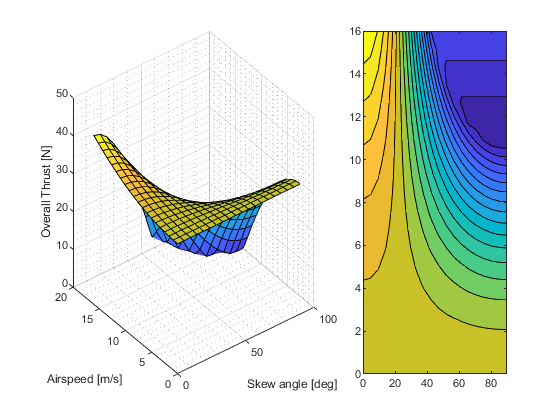

figure(10)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,M_c_roll)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Max Mc Roll [Nm]')
nexttile([1,2])
contourf(rad2deg(L),V,M_c_roll,20)

figure(11)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,M_c_pitch)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Max Mc Pitch [Nm]')
nexttile([1,2])
contourf(rad2deg(L),V,M_c_pitch,20)

figure(12)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,M_c_yaw)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Max Mc Yaw [Nm]')
nexttile([1,2])
contourf(rad2deg(L),V,M_c_yaw,20)
% for ii = 1:size(L,1)
%     for jj = 1:size(L,2)
%         Thrust_surf(ii,jj)= thrust_level(L(ii),V(jj));
%     end
% end

figure(13)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,Thrust_surf)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Thrust level [N]')
nexttile([1,2])
contourf(rad2deg(L),V,Thrust_surf,20)
max_speed = 20 ; %[m/s]
T_bx_max  = 16 ; %[N]
Thrust_bx_surf = 16/(20^2)*V.^2;
figure(14)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,Thrust_bx_surf)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Thrust level Pusher [N]')
nexttile([1,2])
contourf(rad2deg(L),V,Thrust_bx_surf,20)
figure(15)
clf
tiledlayout(1,5);
nexttile([1,3])
surf(rad2deg(L),V,Thrust_bx_surf+Thrust_surf)
grid on
grid minor
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Overall Thrust [N]')
nexttile([1,2])
contourf(rad2deg(L),V,Thrust_bx_surf+Thrust_surf,20)

In order t derive a desired skew set point per considered airspeed we have to fuse the found surfaces in a way that reflects the desired behaviour of the drone. 

**Step 1:**

Normalize the surfaces so that a fair comparison can be carried according to :


$$S_{\textrm{norm}} =\frac{S}{\max \left(||S||\right)}$$


**Step 2:**

Define a fourth surface to represent the power cost of a certain airspeed skew combination. This surface is defined by


$$T_{\textrm{tot}} \left(\Lambda ,v\right)=T_{\textrm{qud}} +T_{\textrm{push}} =\max \left(\textrm{mass}\;g-L\left(\Lambda ,v\right),0\right)+a*v^2$$



$$S_T \left(\Lambda ,v\right)=\frac{1}{T_{\textrm{tot}} \left(\Lambda ,v\right)}$$


**Step 3:**

Fuse the surfaces toghether using weighting factors


$$M_{c_{\textrm{tot}} } =\left\lbrack \begin{array}{cccc}
\gamma_{\phi }  & \gamma_{\theta }  & \gamma_{\psi }  & \gamma_T 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
M_{c_{\phi } } \\
M_{c_{\theta } } \\
M_{c_{\psi } } \\
S_T 
\end{array}\right\rbrack$$


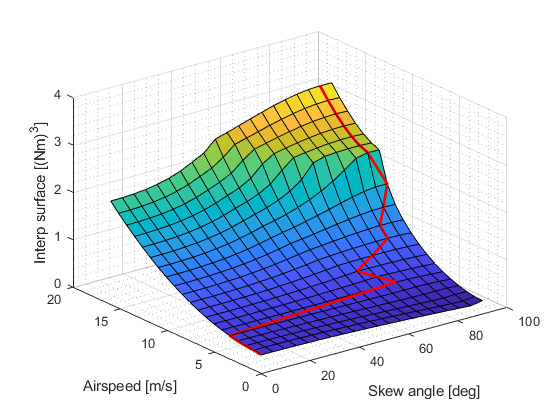

[L,V] = meshgrid(lambda_q,v_q);
gamma = [1,1,1,1];
lift_num = matlabFunction(lift);
%lift_surf = min(mass*g,lift_num(L,V)).*(-1/16*V+1);

lift_surf = 1./(Thrust_bx_surf+Thrust_surf); %UNCOMMENT

lift_off = lift_surf./max(lift_surf(:));
%lift_off = (max(Thrust_surf(:))-Thrust_surf)./max(Thrust_surf(:));
M_c_roll_norm = M_c_roll./ max(M_c_roll(:));
M_c_pitch_norm = M_c_pitch./ max(M_c_pitch(:));
M_c_yaw_norm = M_c_yaw./ max(M_c_yaw(:));
%surf_tot = M_c_roll_norm .* M_c_pitch_norm.*lift_off ;%.* M_c_yaw_norm + 1*lift_off;

surf_tot = gamma(1)*M_c_roll_norm + gamma(2)*M_c_pitch_norm + gamma(3)*M_c_yaw_norm+gamma(4)*lift_off;
%surf_tot = (gamma(1)*M_c_roll_norm + gamma(2)*M_c_pitch_norm + gamma(3)*M_c_yaw_norm).*lift_off;
[Zmax,idx_Z] = max(surf_tot,[],2);
figure(20)
clf
surf(rad2deg(L),V,surf_tot)
grid on
grid minor
hold on 
plot3( rad2deg(lambda_q(idx_Z)),v_q,max(surf_tot,[],2),'-r','LineWidth',2)
%surf(rad2deg(L),V,ones(size(L)).*Zmax(10),'FaceAlpha',0.3)
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Interp surface [(Nm)^3]')

The result is a surface which represent a fusion between the orignal control moment surfaces and the power consuption surface. Now we can evaluate what is the maximum of this surface at each query airspeed and find at which $\Lambda$it occurs. Connecting these maxima will result in a strategy to maximize control across a range of considered airspeeds. 

On the other hand, it can be noticed that sometimes moving inbetween maxima involves first a decrease in control moment. This behaviour is undesired because it would lead to commanded states which actually momentarly decrease control authority. Therefore there is the need to reach the maximum control authority state while always following an ever increasing path.

 In order to reach the maximum point we can then follow a gradient ascend algorithm following the maximum gradient. The most basic example of it uses a constant learning rate $\alpha$ which is followed along the direction of the calculated gradient of the surface.


$$X_{n+1} =X_n +\alpha \;\nabla f\left(X_n \right)$$



$$\nabla f\left(X\right)=\left\lbrack \begin{array}{c}
\frac{\partial }{\partial \Lambda }X\\
\frac{\partial }{\partial v}X
\end{array}\right\rbrack$$


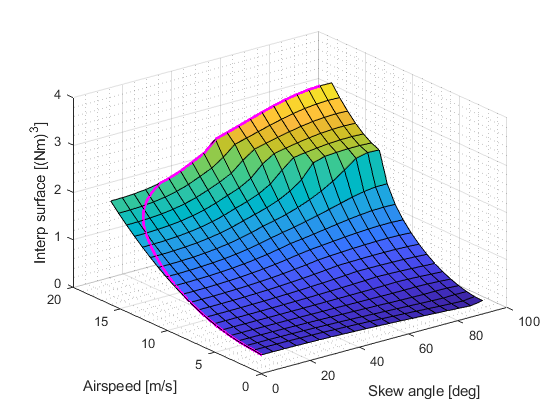

%[fx,fy] = gradient(surf_tot,mean(diff(v_q)),mean(diff(lambda_q)));
[fx,fy] = gradient(surf_tot,rad2deg(mean(diff(lambda_q))),mean(diff(v_q)));
iters = 10000;
n0 = zeros(iters,2);
n0(1,:) = [0 0];
v0 = zeros(iters,1);
v0(1) = interp2(L,V,surf_tot,n0(1,1),n0(1,2));
alpha = 3;%0.55; Settings: Low,High : 0.03,0.03  simple 3
a_des = 0.08;%      Settings: Low,High : 0.01,0.08
I_zz_rp = 2 * (0.20684*0.33813^2+0.15476*0.365^2); %[kgm^2]
L = rad2deg(L);
for idx =2:iters
    delta = alpha.*[interp2(L,V,fx,n0(idx-1,1),n0(idx-1,2)),interp2(L,V,fy,n0(idx-1,1),n0(idx-1,2))]; %original steepest ascend. Direction perpendicular to contour lines. .*[mean(diff(lambda_q)),mean(diff(v_q))]
    %delta = [0.5.*M_c_yaw(ii,jj)./I_zz_rp.*(alpha/a_des).^2,alpha].* [interp2(L,V,fx,n0(idx-1,1),n0(idx-1,2)),interp2(L,V,fy,n0(idx-1,1),n0(idx-1,2))];
    
    %delta = alpha.* [interp2(L,V,fx,n0(idx-1,1),n0(idx-1,2)),0.2]; % fixed
    delta(2)= min(0.002,abs(delta(2)))/sign(delta(2)); % Uncomment for fixed airspeed ascent

    if delta == [0,0]
        delta = [rad2deg(mean(diff(lambda_q))),mean(diff(v_q))];
    end
    n0(idx,:)= n0(idx-1,:) + delta;
    n0(idx,:)= max([0.01,0.01],n0(idx,:));
    n0(idx,:)= min([rad2deg(lambda_q(end)-0.01),v_q(end)-0.01],n0(idx,:));
    if idx <20
        %disp(idx);
        %disp(delta);
        %disp([rad2deg(n0(idx,1)),n0(idx,2)]);
    end
    v0(idx,1) = interp2(L,V,surf_tot,n0(idx,1),n0(idx,2));
end
figure(30)
clf
surf(L,V,surf_tot)
grid on
grid minor
hold on 
plot3(n0(:,1),n0(:,2),v0,'-m','LineWidth',2);
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Interp surface [(Nm)^3]')

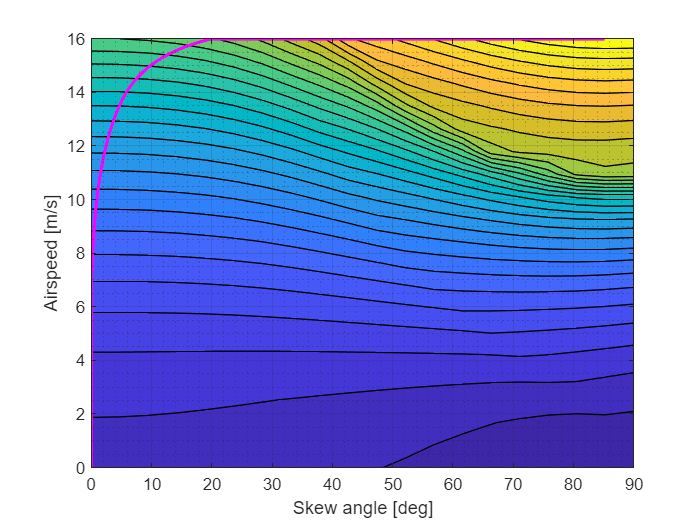

figure(31)
clf
contourf(L,V,surf_tot,30)
grid on
grid minor
hold on 
%quiver(rad2deg(L),V,fx,fy)
plot(n0(:,1),n0(:,2),'-m','LineWidth',2);
xlabel('Skew angle [deg]')
ylabel('Airspeed [m/s]')
zlabel('Interp surface [(Nm)^3]')

%axis equal

**Simple gradient ascent algorithm:**

The problem with the simple gradient ascent algorithm is that, as also deductable from the isometric lines, the stepeer gradient with respect to airspeed (due to elevator and rudder increasingly more effective with the square of airspeed) will bias the algorithm towards rapid increases of airspeed rather than skew angle. Logically such solution is unwanted since transition would be commanded only at very high speed. 

**Airspeed limited learning rate:**

For example, when the drone is crusing at low airspeed next to the ship (and so the speed has to match the speed of the boat) we would still like to maximise control authority by changing the skew angle. Therefore, we would like a solution that increases skew as much as possible given that the gradient of the function is positive at the considered state. 

**Acceleration based learning rate:**

While such strategy might represent a simple an effective solution, it does not account for the fact that the drone is a physical system and the produced skew reference might not be feasible. It could be that a fastly accelerating drone is rapidly increasing airspeed which would in turn result in a commanded change in skew angle which is unachievable on such short timescale. Therefore, there is the need to link the reference skew angle signal to the current acceleration of the drone and assure feasability of the commanded signal. 

Let us consider a state of the drone, having a constant forward acceleration $a$ for a set infinitesimally small delta time step $\Delta t$:


$$\Delta v=a\;\Delta t\Longrightarrow \Delta t=\frac{\Delta v}{a}\;$$
 

One of the reasons why a certain reference skew angle signal might be unfeasible is simple due to the capabilities of the servo which is rotating the wing. Now the software rate limit of the servo/wing combination is:


$$\;{\dot{\Lambda} }_{\max } =0\ldotp 1955\;\left\lbrack \frac{\textrm{rad}}{s}\right\rbrack =11\ldotp 2013\left\lbrack \frac{\deg }{s}\right\rbrack$$


it follows that


$$\Delta \;\Lambda_{\max } =\dot{\Lambda} \;\Delta t=\dot{\Lambda} \;\frac{\Delta v}{a}\;$$


Logically the software limit of the servo is achieved in test flights indicating that the harware limit is actually higher. 

Another potentially more limiting effect could be the maximum yaw control moment that an be exerted to counteract the roation of the wing. 

Now, the maximum angular accelleration that the rotating components can achieve can be calculated with respect to the maximum torque exertable by the drone as :


$$M_{c_{\psi } } \left(\Lambda ,v\right)=I_{\textrm{rp}} \;\ddot{\Lambda} \Longrightarrow \;\ddot{\Lambda} =\frac{M_{c_{\psi } } \left(\Lambda ,v\right)}{I_{\textrm{rp}} }$$


Assuming that the maximum and minimum exertable yawing moments have equal magnitude and that the rotation starts and ends still, the maximum change in skew achievable in a givent time step is 


$$\Delta \;\Lambda_{\max } =\frac{1}{2}\;\ddot{\Lambda} \;{\left(\frac{\Delta v}{a}\right)}^2 \;$$


Now from some measurements of the drone we can calculate the inertia of the rotating parts as:


$$I_{\textrm{rp}} =2*\left(0\ldotp 206*\left(0\ldotp 33813\right)ˆ2+0\ldotp 154*\left(0\ldotp 365\right)ˆ2\right)=0\ldotp 0881\;\left\lbrack {\textrm{kgm}}^2 \right\rbrack \;$$


TO BE WORKED OUT FURTHER

We can then express the learning rate of the ascent algorithm as a function of the acceleration of the drone. 


$$\alpha \left(\Lambda ,v\right)=\left\lbrack \begin{array}{cc}
\Delta v & \min \left(\frac{1}{2}\;\frac{M_{c_{\psi } } \left(\Lambda ,v\right)}{I_{\textrm{rp}} }\;\;{\left(\frac{\Delta v}{a}\right)}^2 ,\;{\dot{\Lambda} }_{\max } \right)
\end{array}\right\rbrack$$


Where $\Delta v$ is a constant small learning rate in the direction of increasing airspeed. We can understand that the learning rate in the direction of increasing $\Lambda$ 


$${\alpha \left(\Lambda ,v\right)}_{a\to \infty } \left\lbrack \begin{array}{cc}
\Delta v & 0
\end{array}\right\rbrack \;$$



$${\alpha \left(\Lambda ,v\right)}_{a\to 0} \left\lbrack \begin{array}{cc}
\Delta v & {\dot{\Lambda} }_{\max } 
\end{array}\right\rbrack \;$$


Which in pratical turns it means that if the drone is aggressively accelerating then the ascent path will be more biased toward changing airspeed as the drone would not be able to change the skew as fast. On the other hand, if the velocity is constant (e.g. cruising next to the ship or in the wind tunnel) then the ascent is more biased towards increasing control authority by changing the skew angle. 

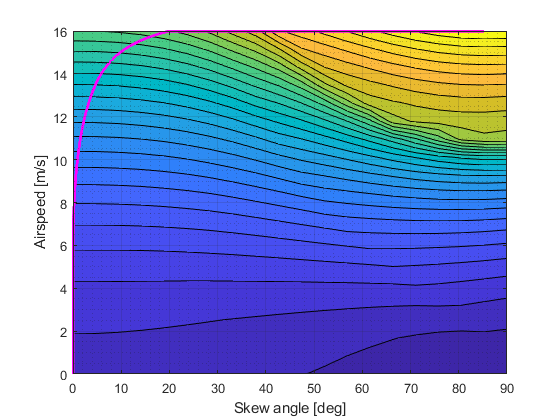

[L,V] = meshgrid(lambda_q,v_q);
test_surf=sin(L).*cos(L)+V.^2./16^2;%sin(L).*cos(L)+V.^2./16^2+sin(L).*V;%
[fx_t,fy_t] = gradient(test_surf,rad2deg(mean(diff(lambda_q))),mean(diff(v_q)));
L = rad2deg(L);
figure(200)

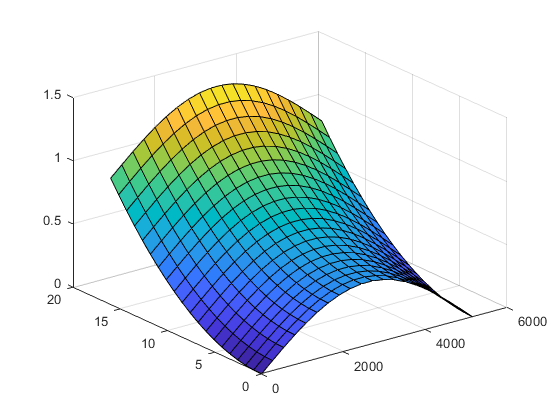

clf
surf(rad2deg(L),V,test_surf)
figure(201)

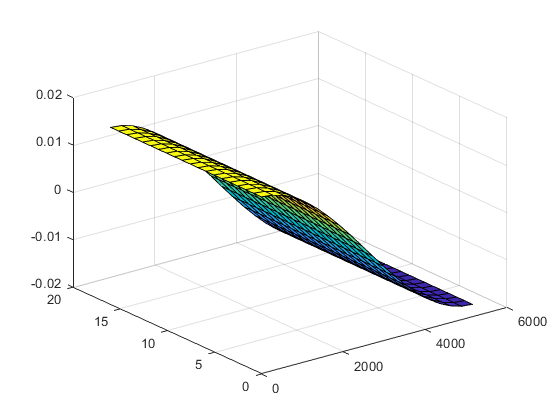

clf
surf(rad2deg(L),V,fx_t)
figure(202)

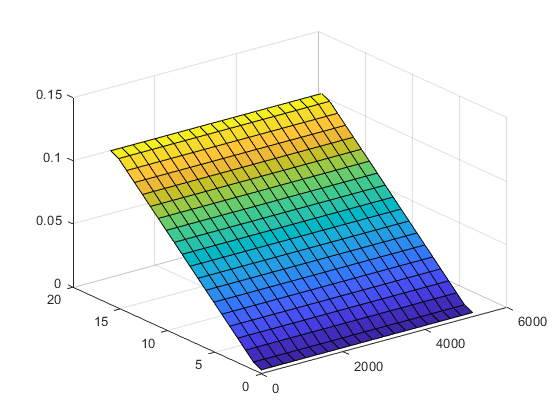

clf
surf(rad2deg(L),V,fy_t)
iters = 2000;
n0 = zeros(iters,2);
n0(1,:) = [deg2rad(20) 2];
v0 = zeros(iters,1);
v0(1) = interp2(L,V,test_surf,n0(1,1),n0(1,2));
alpha = 0.55;%0.55;
a_des = 1;
for idx =2:iters
    delta = alpha.*[interp2(L,V,fx_t,n0(idx-1,1),n0(idx-1,2)),interp2(L,V,fy_t,n0(idx-1,1),n0(idx-1,2))]; %original steepest ascend. Direction perpendicular to contour lines. .*[mean(diff(lambda_q)),mean(diff(v_q))]
    %delta = [alpha,0.5*0.1*(alpha/a_des)^2].* [interp2(L,V,fx,n0(idx-1,1),n0(idx-1,2)),interp2(L,V,fy,n0(idx-1,1),n0(idx-1,2))];
    
    %delta = alpha.* [interp2(L,V,fx,n0(idx-1,1),n0(idx-1,2)),0.2]; % fixed
    %delta(2)= min(0.002,abs(delta(2)))/sign(delta(2));
    if delta == [0,0]
        delta = [0,mean(diff(v_q))];
    end
    n0(idx,:)= n0(idx-1,:) + delta;
    v0(idx,1) = interp2(L,V,test_surf,n0(idx,1),n0(idx,2));
end

figure(203)

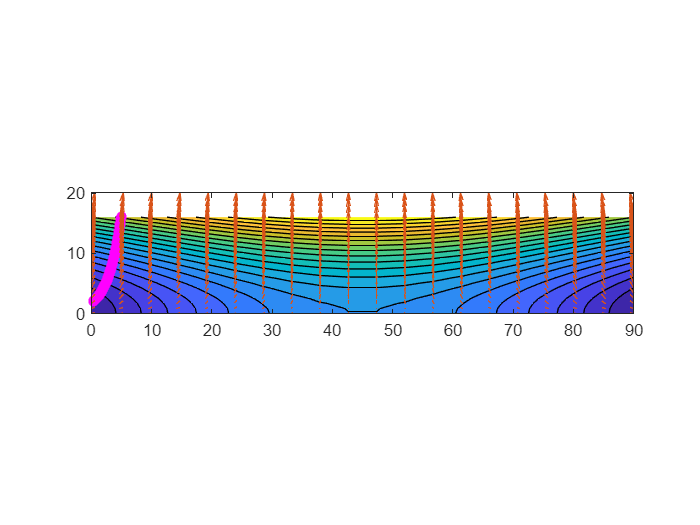

clf
contourf(L,V,test_surf,20)
hold on
plot(n0(:,1),n0(:,2),'-*m','LineWidth',2);
quiver(L,V,fx_t,fy_t)
axis equal

% figure(21)
% clf
% surf(rad2deg(L),V,fx)
% hold on
% surf(rad2deg(L),V,zeros(size(L)),'FaceAlpha',0.3)
% xlabel('Skew angle [deg]')
% ylabel('Airspeed [m/s]')
% zlabel('Gradient in X')
% figure(22)
% clf
% surf(rad2deg(L),V,fy)
% hold on
% surf(rad2deg(L),V,zeros(size(L)),'FaceAlpha',0.3)
% xlabel('Skew angle [deg]')
% ylabel('Airspeed [m/s]')
% zlabel('Gradient in Y')
% x = 1;
% y = 1;
% count = 0;
% state = 0;
% x_save = [];
% y_save = [];
% z_save = [];
% %while state<90
% for count = 1:40
%     %count =+ 1;
%     fx(x,y);
%     fy(x,y);
%     if fx(x,y)>fy(x,y)
%         y = y+ 1;
%     else
%         x = x+ 1;
%     end
%     state = lambda_q(x);
%     x_save=[x_save,x];
%     y_save = [y_save,y];
%     z_save = [z_save,surf_tot(x,y)];
%     if x==20 || y==20
%         break
%     end
% end
% x2 = 1;
% y2 = 1;
% count2 = 0;
% state = 0;
% x_save2 = [];
% y_save2 = [];
% z_save2 = [];
% %while state<90
% for count = 1:40
%     %count =+ 1;
%     fx(x2,y2);
%     fy(x2,y2);
%     if fx(x2,y2)>0
%         y2 = y2+ 1;
%     else
%         x2 = x2+ 1;
%     end
%     
%     x_save2=[x_save2,x2];
%     y_save2 = [y_save2,y2];
%     z_save2 = [z_save2,surf_tot(x2,y2)];
%     if x2==20 || y2==20
%         break
%     end
% end
% figure(23)
% clf
% surf(rad2deg(L),V,surf_tot)
% grid on
% grid minor
% hold on 
% plot3( rad2deg(lambda_q(idx_Z)),v_q,max(surf_tot,[],2),'-r','LineWidth',2)
% plot3(rad2deg(lambda_q(y_save)),v_q(x_save),z_save,'-m','LineWidth',2)
% plot3(rad2deg(lambda_q(y_save2)),v_q(x_save2),z_save2,'-c','LineWidth',2)
% %surf(rad2deg(L),V,ones(size(L)).*Zmax(10),'FaceAlpha',0.3)
% xlabel('Skew angle [deg]')
% ylabel('Airspeed [m/s]')
% zlabel('Interp surface [(Nm)^3]')

% [c,r] = find(bsxfun(@eq, surf_tot, max(surf_tot, [], 2)).');
% output = [r,c]

% M_final(Lambda,omega_1,omega_2,omega_3,omega_4,delta_al,delta_ar,delta_el,delta_ru,v)=vpa(M_c_tot(Lambda,b_mot(1),k_mot(1),k_torq_mot(1),omega_1,omega_2,omega_3,omega_4,b_as(1),b_as(3),b_as(4),k_as(1),k_as(2),k_as(3),k_as(4),delta_al,delta_ar,delta_el,delta_ru,v),3)
% dMdL(Lambda,omega_1,omega_2,omega_3,omega_4,delta_al,delta_ar,delta_el,delta_ru,v) = diff(M_final(Lambda,omega_1,omega_2,omega_3,omega_4,delta_al,delta_ar,delta_el,delta_ru,v),Lambda)
% dMdL_num =  matlabFunction(dMdL(Lambda,1,1,1,1,1,1,1,1,v));
% 
% dMdL_surf = zeros(size(L));
% for ii = 1:size(L,1)
%     for jj = 1:size(L,2)
%         temp = dMdL_num(L(ii),V(jj));
%         dMdL_surf(ii,jj) = temp(1);
%     end
% end
% 
% figure(14)
% clf
% surf(rad2deg(L),V,dMdL_surf)
% grid on 
% grid minor
% xlabel('Skew angle [deg]')
% ylabel('Airspeed [m/s]')
% zlabel('Max Mc Pitch [Nm]')